# Testing conductivity maps


% Initializing data

rootPath=initialize_root_path();
load([rootPath,'energy-height-conversion\Tools\Projects\Paper 1\Data\Ground\pfisr_data_26_Mar_2008.mat']);

time = pfisrBeamAvg.density.time;
timeStr = '2008 03 26 9:00:00';
timeIndex = find_time(time, timeStr);

alt = pfisrBeamAvg.density.alt(1:end);
% density = pfisrBeamAvg.density.electron(1:end,timeIndex)';
density = ones(1, length(alt));
lat = 65;
lon = -147;



% Running the conductivity function (using IRI2016)
alt = 80:1:300;
output = get_conductivity_v1(alt, density, lat, lon, datenum(timeStr), 1);

Error using msis>parseresult (line 519)
The online interface returned:


404 Not Found

Not Found
The requested URL /cgi/vitmo/vitmo_model.cgi was not found on this server.



Error in msis (line 365)
                    (index-1)) = parseresult(fpath, sweeplen(index));

Error in 

## Plotting data

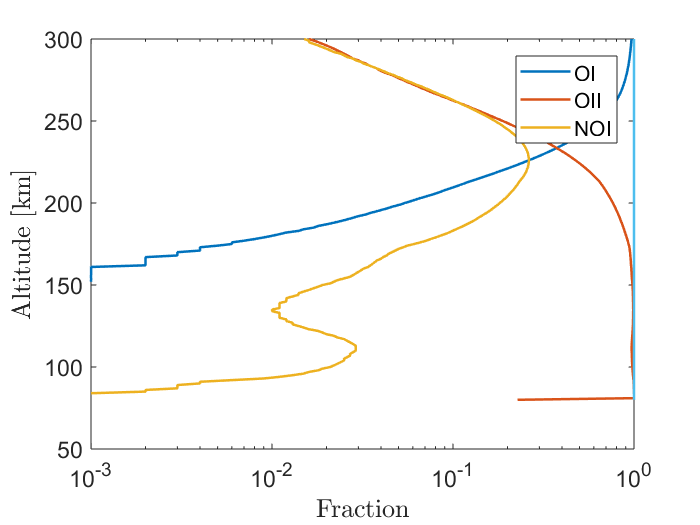


% Ion composition
figure;
plot(output.C, output.alt);
hold on;
plot(sum(output.C,2),output.alt);
set(gca, 'XScale', 'log');
legend('OI', 'OII', 'NOI');
xlabel('Fraction');
ylabel('Altitude [km]');

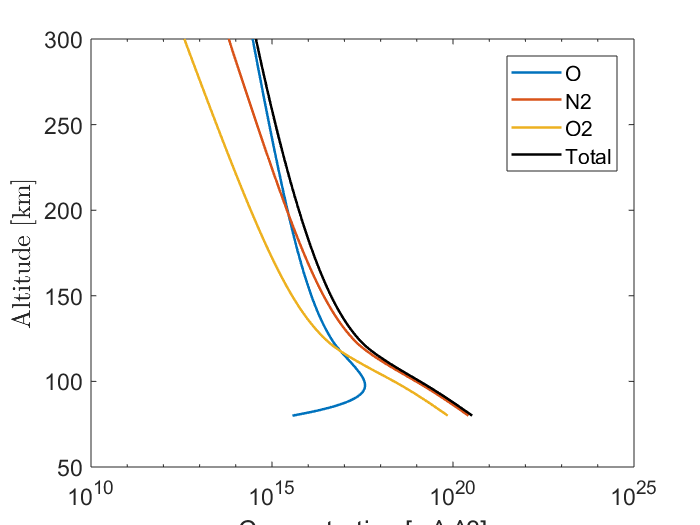

% Neutral composition
figure;
plot(output.Nn, output.alt);
hold on;
plot(output.N, output.alt,'k');
set(gca, 'XScale', 'log');
legend('O' , 'N2', 'O2' ,'Total');
xlabel('Concentration [m^-^3]');
ylabel('Altitude [km]');

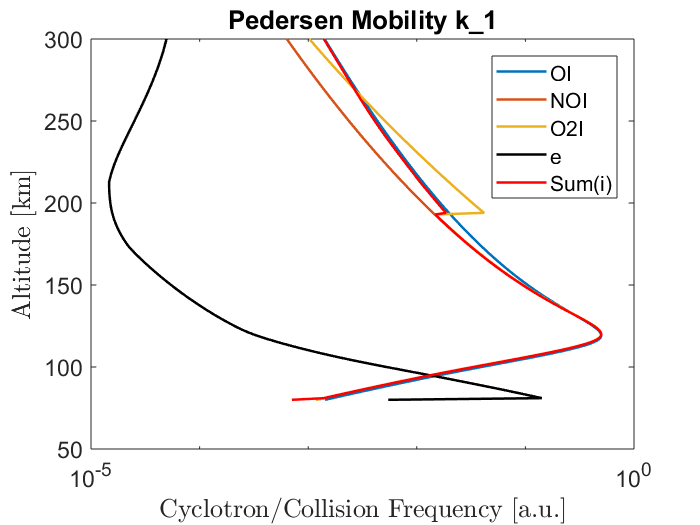

% Plot Pedersen mobility

figure;
B = zeros(length(output.alt),1);
for i=1:1:3
        A = output.k_i(:,i)./(1+output.k_i(:,i).^2);
        B = B + output.C(:,i).*A;
        plot(A, output.alt);
        hold on;
end
 plot(output.k_e./(1+output.k_e.^2), output.alt,'k');
 hold on;
 plot(B, output.alt, 'r');
set(gca, 'XScale', 'log');
legend('OI' , 'NOI', 'O2I' , 'e', 'Sum(i)');
xlabel('Cyclotron/Collision Frequency [a.u.]');
ylabel('Altitude [km]');
title('Pedersen Mobility k_1');

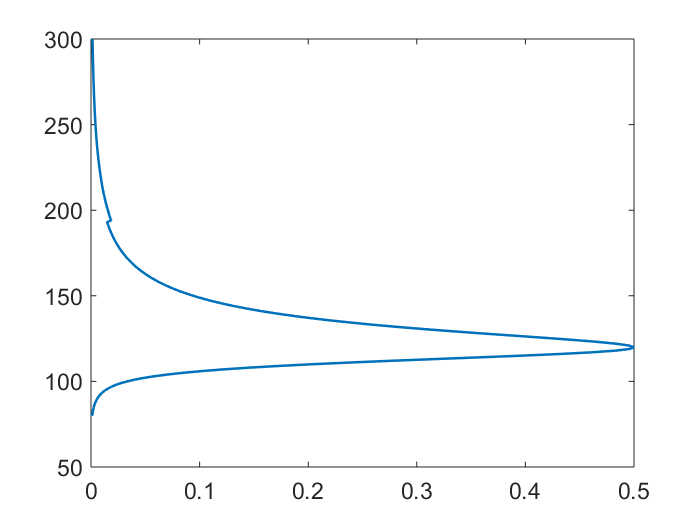

figure; plot(B,output.alt);

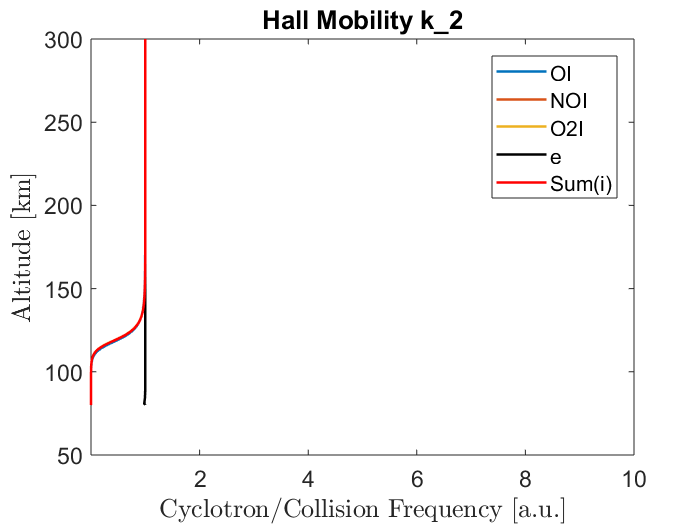

% Plot hall mobility 1

figure;
B = zeros(length(output.alt),1);
for i =1:1:3
        A = (output.k_i(:,i).^2)./(1+output.k_i(:,i).^2);
        B = B + output.C(:,i).*A;
        plot(A, output.alt);
        hold on;

end
 plot((output.k_e.^2)./(1+output.k_e.^2), output.alt,'k');
 hold on;
 plot(B, output.alt, 'r');
set(gca, 'XScale', 'linear');
xlim([10^-5 10^1]);
legend('OI' , 'NOI', 'O2I', 'e', 'Sum(i)');
xlabel('Cyclotron/Collision Frequency [a.u.]');
ylabel('Altitude [km]');
title('Hall Mobility k_2');

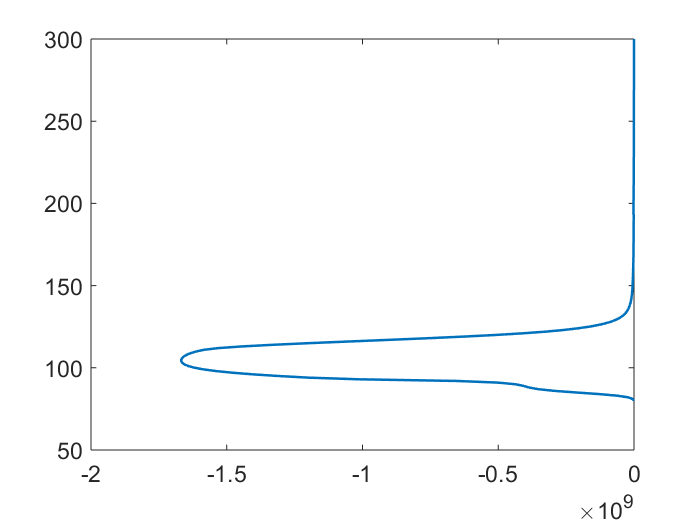


figure;
plot(output.ne.*(B-(output.k_e.^2)./(1+output.k_e.^2)),output.alt);

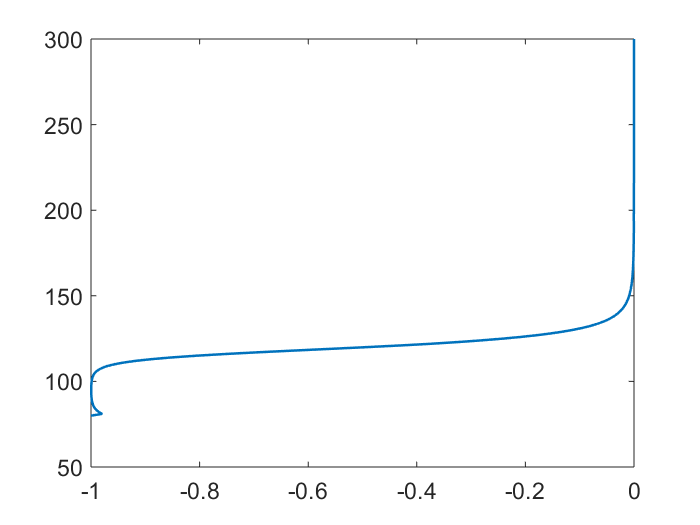

figure;
plot((B-(output.k_e.^2)./(1+output.k_e.^2)),output.alt);

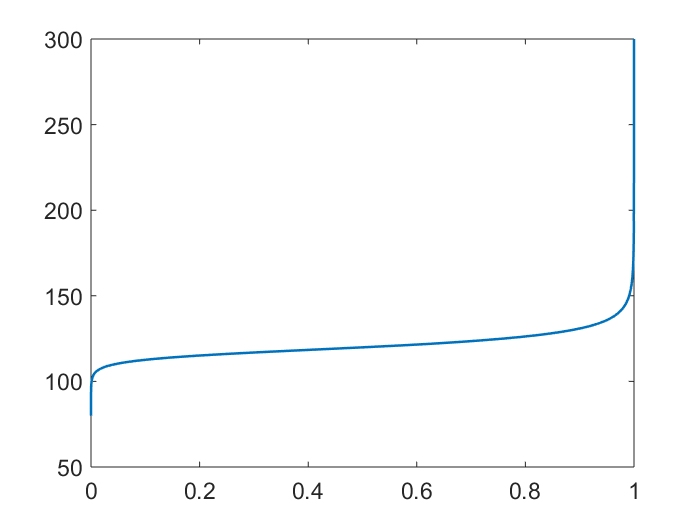

figure; plot(B,output.alt);

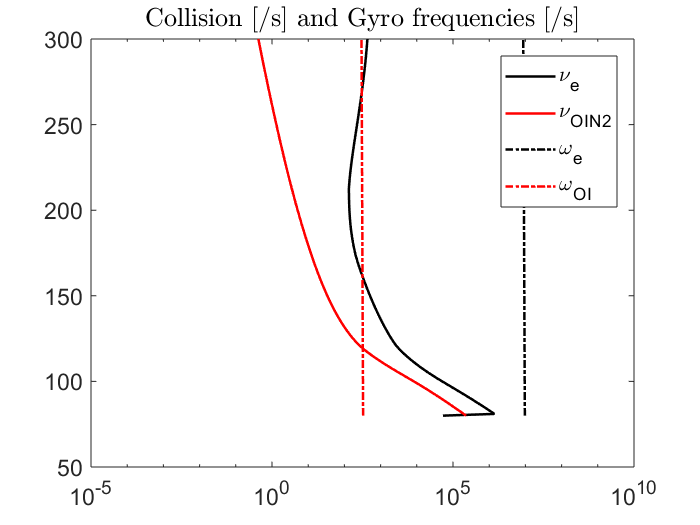


% Collision Frequency
figure;
ion=1;     %[ OI, OII, NOI]
plot(output.v_e, output.alt, 'k');
hold on;
plot(output.v_i(:,ion), output.alt, 'r');
hold on;
plot(output.w_e, output.alt, '-.k');
hold on;
plot(output.w_i(:,ion), output.alt, '-.r');
set(gca,'XScale','log');
title('Collision [/s] and Gyro frequencies [/s]');
legend('\nu_e', '\nu_O_I_N_2', '\omega_e', '\omega_O_I');

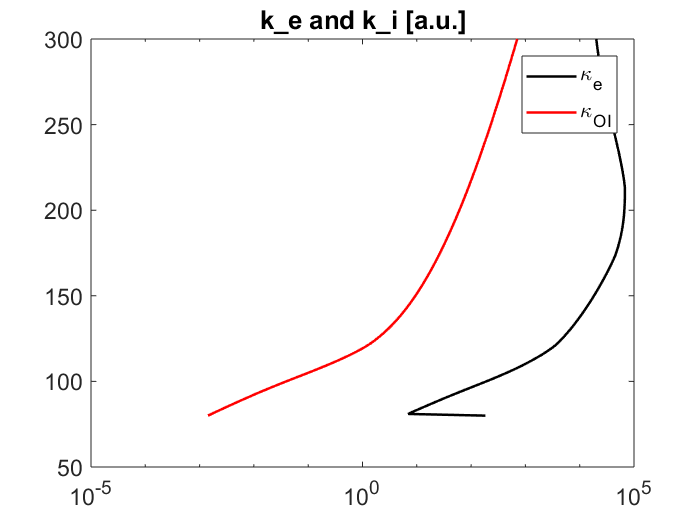

% Intermediate plot of k_e and k_i
figure;
plot(output.k_e, output.alt, 'k');
hold on;
plot(output.k_i(:,ion), output.alt, 'r');
set(gca,'XScale','log');
title('k_e and k_i [a.u.]');
legend('\kappa_e', '\kappa_O_I');

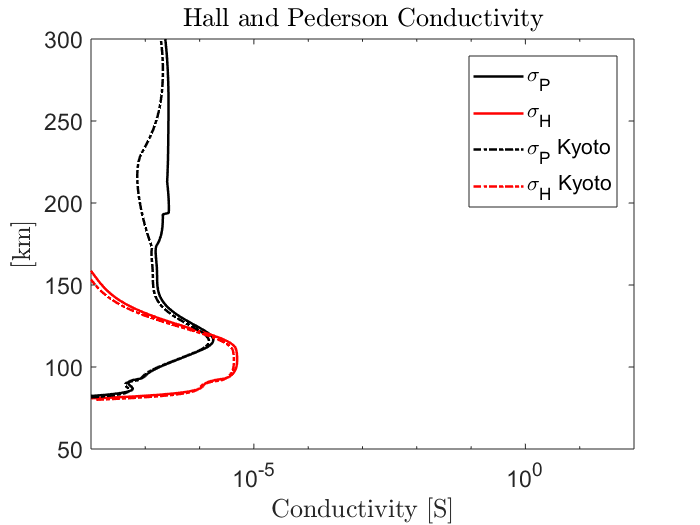


% Sigma_H and Sigma_P
load('C:\Users\Nithin\Documents\GitHub\energy-height-conversion\Tools\Projects\Paper 2\Data\IRI2016_Conductivity_Profile.mat');
figure;

plot(output.sigma_P, output.alt, 'k');
hold on;
plot(output.sigma_H, output.alt, 'r');
set(gca, 'XScale', 'log');
title('Hall and Pederson Conductivity');

xlabel('Conductivity [S]');
ylabel('[km]');


hold on;
xlim([10^-8 10^2]);

hold on;
plot(S1,HEIGHT,'-.k');
hold on;
plot(S2,HEIGHT,'-.r');
legend('\sigma_P','\sigma_H', '\sigma_P Kyoto', '\sigma_H Kyoto');
hold off;

## Height integrated conductivities

HeightFinalIndx = find_altitude(HEIGHT,250);
HeightInitialIndx = find_altitude(HEIGHT,80);
AltFinalIndx = find_altitude(output.alt,250);
AltInitialIndx = find_altitude(output.alt,80);
Sum_S1 = trapz(HEIGHT(HeightInitialIndx:HeightFinalIndx),S1(HeightInitialIndx:HeightFinalIndx))*1000;
Sum_S2 = trapz(HEIGHT(HeightInitialIndx:HeightFinalIndx),S2(HeightInitialIndx:HeightFinalIndx))*1000;
Sum_sigma_H = trapz(output.alt(AltInitialIndx:AltFinalIndx), output.sigma_H(AltInitialIndx:AltFinalIndx))*1000;
Sum_sigma_P = trapz(output.alt(AltInitialIndx:AltFinalIndx), output.sigma_P(AltInitialIndx:AltFinalIndx))*1000;

disp(['Sigma_P_Kyoto = ',num2str(Sum_S1,3),' S']);

Sigma_P_Kyoto = 0.0412 S


disp(['Sigma_P = ',num2str(Sum_sigma_P,3),' S']);

Sigma_P = 0.0586 S


disp(['Sigma_H_Kyoto = ',num2str(Sum_S2,3),' S']);

Sigma_H_Kyoto = 0.115 S


disp(['Sigma_H = ',num2str(Sum_sigma_H,3),' S']);

Sigma_H = 0.131 S


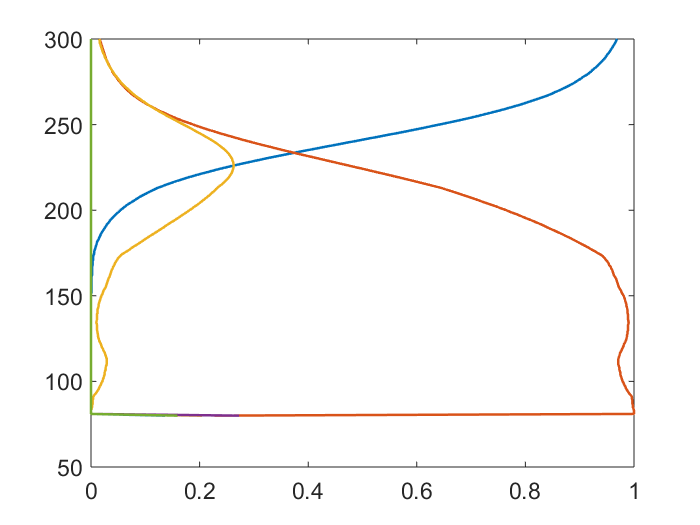



% figure;
% plot((sum(output.E,2)),output.alt);

figure;
plot(output.C,output.alt);